# Practical Introduction to Frequency-Domain Analysis

This example shows how to perform and interpret basic frequency-domain signal analysis. The example discusses the advantages of using frequency-domain versus time-domain representations of a signal and illustrates basic concepts using simulated and real data. The example answers basic questions such as: what is the meaning of the magnitude and phase of an FFT? Is my signal periodic? How do I measure power? Is there one, or more than one signal in this band?

Frequency-domain analysis is a tool of utmost importance in signal processing applications. Frequency-domain analysis is widely used in such areas as communications, geology, remote sensing, and image processing. While time-domain analysis shows how a signal changes over time, ***frequency-domain analysis shows how the signal's energy is distributed over a range of frequencies***. A frequency-domain representation also includes information on the phase shift that must be applied to each frequency component in order to recover the original time signal with a combination of all the individual frequency components.

A signal can be converted between the time and frequency domains with a pair of mathematical operators called a transform. An example is the Fourier transform, which decomposes a function into the sum of a (potentially infinite) number of sine wave frequency components. ***The 'spectrum' of frequency components is the frequency domain representation of the signal***. The inverse Fourier transform converts the frequency domain function back to a time function. The **fft** and **ifft** functions in MATLAB allow you to compute the Discrete Fourier transform (DFT) of a signal and the inverse of this transform respectively.

## Magnitude and Phase Information of the FFT

***The frequency-domain representation of a signal carries information about the signal's magnitude and phase at each frequency. This is why the output of the FFT computation is complex***. A complex number, $x$, has a real part, $x_r$, and an imaginary part, $x_i$, such that $x = x_r + ix_i$. The magnitude of $x$ is computed as $\sqrt{(x_r^2+x_i^2)}$, and the phase of $x$ is computed as $\arctan{(x_i/x_r)}$. You can use MATLAB functions **abs** and **angle** to respectively get the magnitude and phase of any complex number.

Use an audio example to develop some insight on what information is carried by the magnitude and the phase of a signal. To do this, load an audio file containing 15 seconds of acoustic guitar music. The sample rate of the audio signal is 44.1 kHz.

clc
clear
close all

Fs = 44100;
y = audioread('guitartune.wav');

plot the original signal

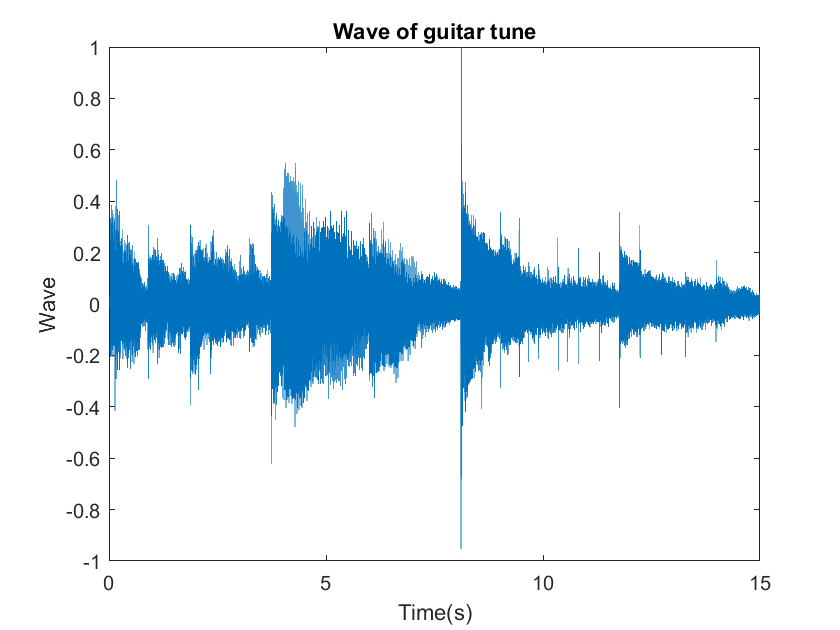

NFFT = length(y);

figure
x=(0:1/Fs:(NFFT-1)/Fs)';
plot(x,y);
xlabel('Time(s)');
ylabel('Wave');
title('Wave of guitar tune')

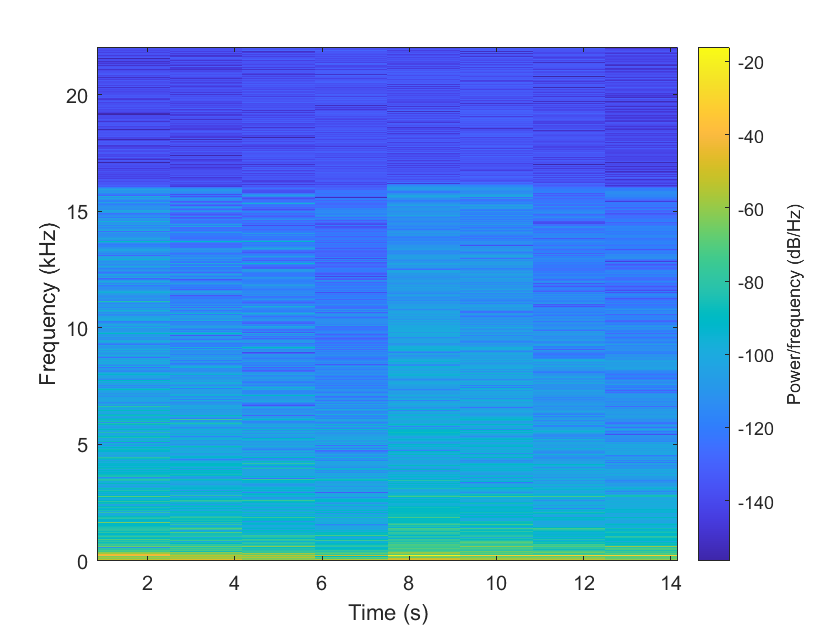


figure
spectrogram(y,[],[],[],Fs,'yaxis')

The output of the FFT is a complex vector containing information about the frequency content of the signal. ***The magnitude tells you the strength of the frequency components relative to other components***. ***The phase tells you how all the frequency components align in time.***

Plot the magnitude and the phase components of the frequency spectrum of the signal. The magnitude is conveniently plotted in a logarithmic scale (dB). The phase is unwrapped using the **unwrap** function so that we can see a continuous function of frequency.

Use **fft** to observe the frequency content of the signal. 

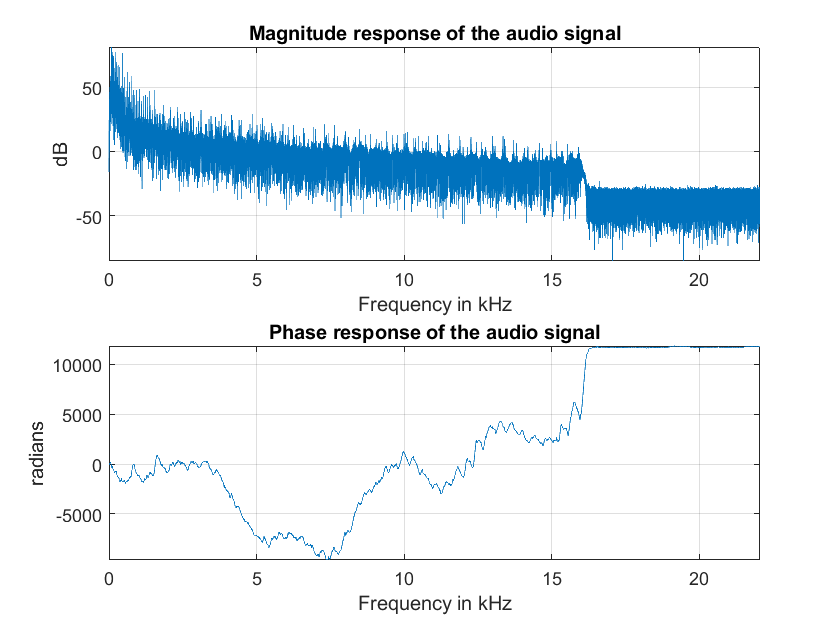

Y = fft(y,NFFT);
F = ((0:1/NFFT:1-1/NFFT)*Fs).';

magnitudeY = abs(Y);        % Magnitude of the FFT
% phaseY = (angle(Y));  % Phase of the FFT
phaseY = unwrap(angle(Y));  % Phase of the FFT


helperFrequencyAnalysisPlot1(F,magnitudeY,phaseY,NFFT)

***You can apply an inverse Fourier transform to the frequency domain vector, Y, to recover the time signal***. The *'symmetric' flag tells ****ifft**** that you are dealing with a real-valued time signal so it will zero out the small imaginary components that appear on the inverse transform due to numerical inaccuracies in the computations.* Notice that the original time signal, y, and the recovered signal, y1, are practically the same (the norm of their difference is on the order of 1e-14). The very small difference between the two is also due to the numerical inaccuracies mentioned above. Play and listen the un-transformed signal y1.

y1 = ifft(Y,NFFT,'symmetric');
norm(y-y1)

ans = 3.8011e-14

% hplayer1 = audioplayer(y, Fs);
% play(hplayer1);
% 
% hplayer2 = audioplayer(y1, Fs);
% play(hplayer2);
% 
% figure
% plot(x,y,'k-',x,y1,'--b')
% xlabel('Time(s)');
% ylabel('Wave');
% title('Fourier and inverse fourier transform Wave of guitar tune')
% legend('y','y1')

To see the effects of changing the magnitude response of the signal, remove frequency components above 1 kHz directly from the FFT output (by making the magnitudes equal to zero) and listen to the effect this has on the sound of the audio file. Removing high frequency components of a signal is referred to as lowpass filtering.

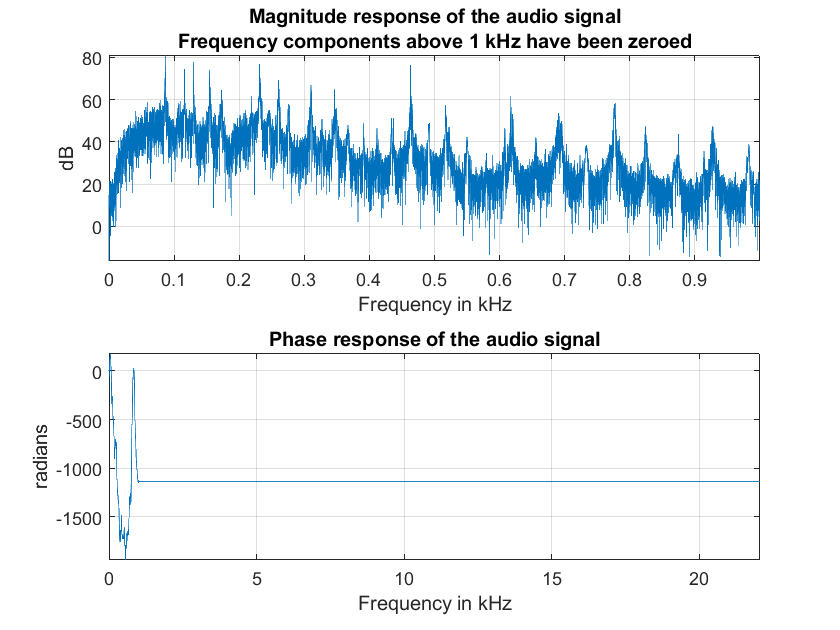

Ylp = Y;
Ylp(F>=1000 & F<=Fs-1000) = 0;

helperFrequencyAnalysisPlot1(F,abs(Ylp),unwrap(angle(Ylp)),NFFT,...
  'Frequency components above 1 kHz have been zeroed')

Get the filtered signal back into time domain using **ifft**. 

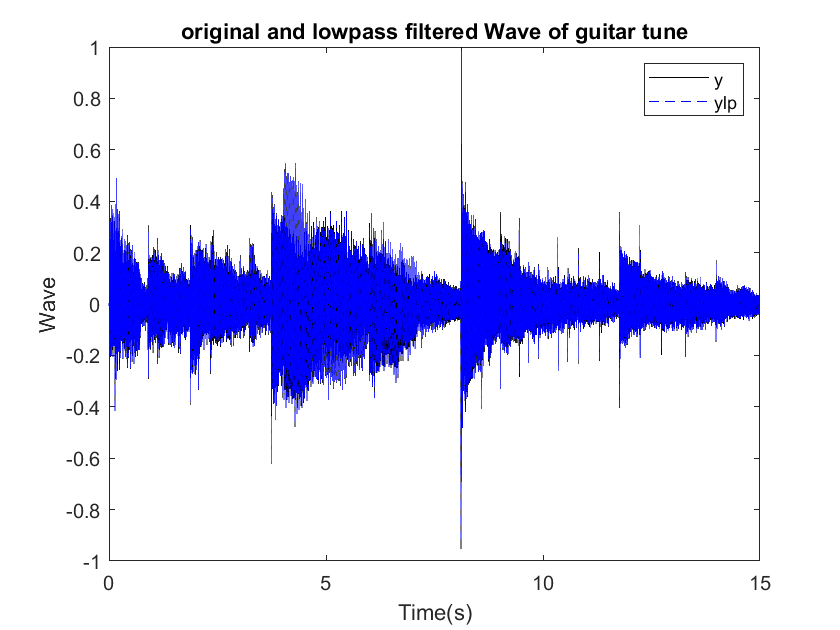

ylp = ifft(Ylp,'symmetric');

figure
plot(x,y,'k-',x,ylp,'--b')
xlabel('Time(s)');
ylabel('Wave');
title('original and lowpass filtered Wave of guitar tune')
legend('y','ylp')

Play the signal. You can still hear the melody but it sounds like if you had covered your ears (you filter high frequency sounds when you do this). Even though guitars produce notes that are between 400 and 1 kHz, as you play a note on a string, the string also vibrates at multiples of the base frequency. These higher frequency components, referred to as harmonics, are what give the guitar its particular tone. When you remove them, you make the sound seem "opaque".

hplayer = audioplayer(ylp, Fs);
play(hplayer);

The phase of a signal has important information about when in time the notes of the song appear. To illustrate the importance of phase on the audio signal, remove the phase information completely by taking the magnitude of each frequency component. Note that by doing this you keep the magnitude response unchanged.

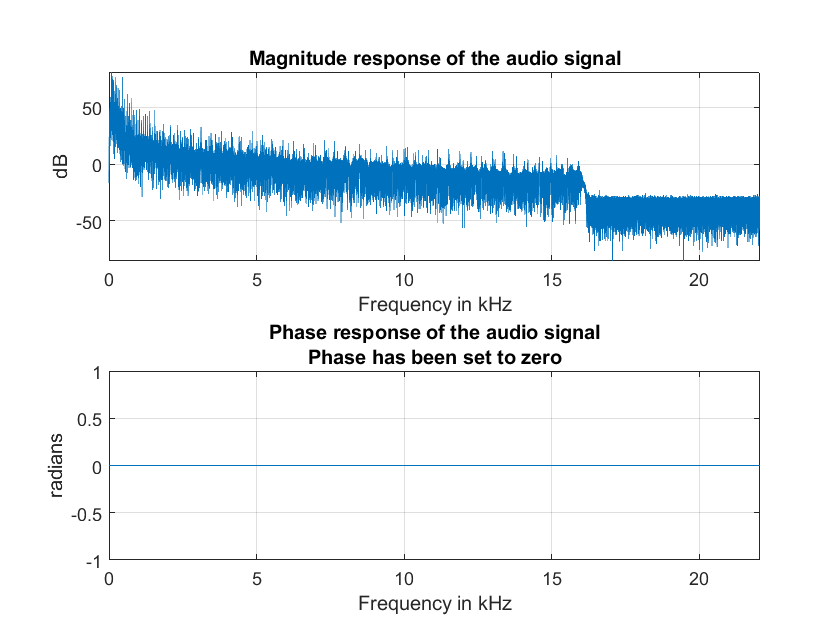

% Take the magnitude of each FFT component of the signal
Yzp = abs(Y);
helperFrequencyAnalysisPlot1(F,abs(Yzp),unwrap(angle(Yzp)),NFFT,[],...
  'Phase has been set to zero')

Get the signal back in the time domain and play the audio. You cannot recognize the original sound at all. The magnitude response is the same, no frequency components have been removed this time, but the order of the notes has disappeared completely. The signal now consists of a group of sinusoids all aligned at time equal to zero. In general, phase distortions caused by filtering can damage a signal to the point of rendering it unrecognizable.

yzp = ifft(Yzp,'symmetric');
hplayer = audioplayer(yzp, Fs);
play(hplayer);